# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 28-Oct-2019 19:31:47

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Date", "Temp"];
opts.VariableTypes = ["datetime", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Date", "InputFormat", "yyyy-MM-dd");

% Import the data
dailymintemperatures = readtable("C:\Users\darrahts\Dropbox\timeSeriesAnalysis\datasets\daily-min-temperatures.csv", opts)

## Clear temporary variables

clear opts

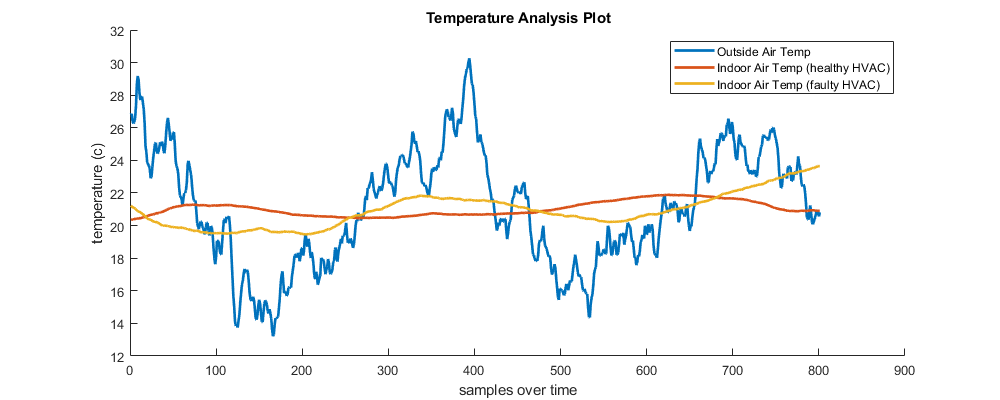

f1 = figure(1); clf;
f1.Position = [0 0 1000 400];
hold on;
plot(smoothdata(mintemps.Temp(400:1200), 'movmean', 10)+10, 'linew', 2);
plot(smoothdata(mintemps.Temp(400:1200), 'movmean', 700)+10, 'linew', 2);
plot(smoothdata(mintemps.Temp(400:1200), 'movmean', 300)+10, 'linew', 2);
hold off;
title("Temperature Analysis Plot");
xlabel("samples over time");
ylabel("temperature (c)");
legend(["Outside Air Temp", "Indoor Air Temp (healthy HVAC)", "Indoor Air Temp (faulty HVAC)"]);